%导入数据
clear;clc
bankData=cell(3,2);
for i=1:3
    %读取对应年份数据
    year=int2str(2009+i);
    temp=readtable("商业银行指标数据.xls","Sheet",year);
    bankData{i,1}=year;
    bankData{i,2}=table2array(temp(:,2:end)); 
end

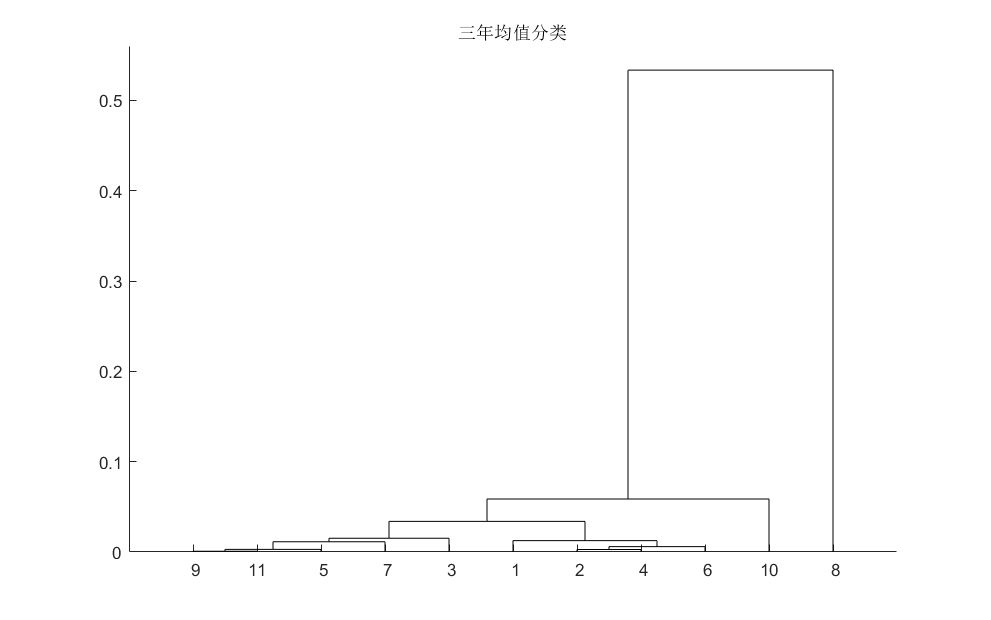

%银行名称列表
nameList=table2cell(temp(:,1));
%数据对应名称
variableTable={'固定资产净值' '经营费用'	'利息支出' '营业支出' '资产总计'	'员工人数' '利润总额' '投资收益' '存款' '贷款' '营业收入'};
%求三年
yearAverage=zeros(size(bankData{i,2},1),size(bankData{i,2},2));
for i=1:3
    yearAverage=yearAverage+bankData{i,2};
end
yearAverage=yearAverage./i;
%利用三年均值分类，寻找相关性较强的数据
d=pdist(yearAverage','correlation');
z=linkage(d,'average');
h=dendrogram(z);
set(h,'Color','k')
T=cluster(z,'maxclust',4);
title("三年均值分类");

for i=1:4
    tm=find(T==i);
    tm=reshape(tm,1,length(tm));
    temp6={};
    %设置导出内容
    for j=1:length(tm)
        temp6{j}=[int2str(tm(j)) variableTable{tm(j)}];
    end
    fprintf("第%d类的有:",i);
    for l=1:length(temp6)
        fprintf(temp6{l}+" ")
    end
end

第1类的有:

1固定资产净值 2经营费用 4营业支出 6员工人数 

第2类的有:

3利息支出 5资产总计 7利润总额 9存款 11营业收入 

第3类的有:

10贷款 

第4类的有:

8投资收益 

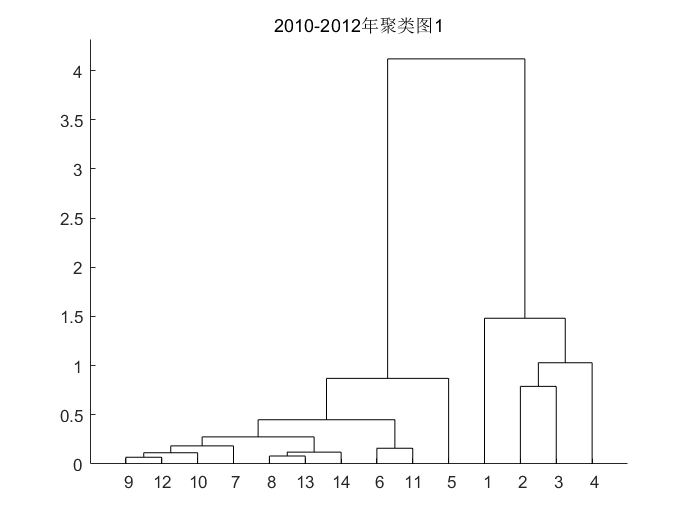

划分成3类的结果如下:
第1类的有:
1中国银行 
第2类的有:
2工商银行 3建设银行 4农业银行 
第3类的有:
5交通银行 6招商银行 7光大银行 8中信银行 9广发银行 10华夏银行 11民生银行 12平安银行 13浦发银行 14兴业银行 
*******************
划分成4类的结果如下:
第1类的有:
4农业银行 
第2类的有:
2工商银行 3建设银行 
第3类的有:
1中国银行 
第4类的有:
5交通银行 6招商银行 7光大银行 8中信银行 9广发银行 10华夏银行 11民生银行 12平安银行 13浦发银行 14兴业银行 
*******************
划分成5类的结果如下:
第1类的有:
5交通银行 
第2类的有:
6招商银行 7光大银行 8中信银行 9广发银行 10华夏银行 11民生银行 12平安银行 13浦发银行 14兴业银行 
第3类的有:
4农业银行 
第4类的有:
2工商银行 3建设银行 
第5类的有:
1中国银行 


%以三年平均数据中1固定资产净值 2经营费用 4营业支出 6员工人数进行分类 
tempData=yearAverage(:,[1 2 4 6]);
T="2010-2012年聚类图1";
drawCluster(tempData,nameList,T);

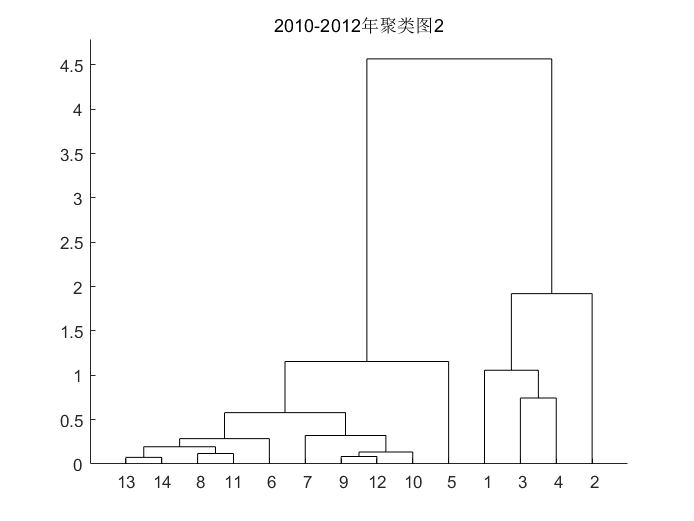

划分成3类的结果如下:
第1类的有:
2工商银行 
第2类的有:
1中国银行 3建设银行 4农业银行 
第3类的有:
5交通银行 6招商银行 7光大银行 8中信银行 9广发银行 10华夏银行 11民生银行 12平安银行 13浦发银行 14兴业银行 
*******************
划分成4类的结果如下:
第1类的有:
5交通银行 
第2类的有:
6招商银行 7光大银行 8中信银行 9广发银行 10华夏银行 11民生银行 12平安银行 13浦发银行 14兴业银行 
第3类的有:
2工商银行 
第4类的有:
1中国银行 3建设银行 4农业银行 
*******************
划分成5类的结果如下:
第1类的有:
1中国银行 
第2类的有:
3建设银行 4农业银行 
第3类的有:
5交通银行 
第4类的有:
6招商银行 7光大银行 8中信银行 9广发银行 10华夏银行 11民生银行 12平安银行 13浦发银行 14兴业银行 
第5类的有:
2工商银行 


%以三年平均数据中3利息支出 5资产总计 7利润总额 9存款 11营业收入进行分类
tempData=yearAverage(:,[3 5 7 9 11]);
T="2010-2012年聚类图2";
drawCluster(tempData,nameList,T);

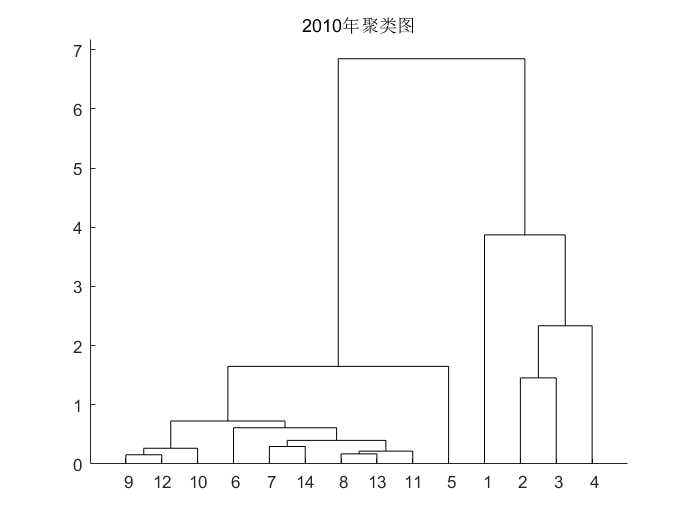

划分成3类的结果如下:
第1类的有:
1中国银行 
第2类的有:
2工商银行 3建设银行 4农业银行 
第3类的有:
5交通银行 6招商银行 7光大银行 8中信银行 9广发银行 10华夏银行 11民生银行 12平安银行 13浦发银行 14兴业银行 
*******************
划分成4类的结果如下:
第1类的有:
4农业银行 
第2类的有:
2工商银行 3建设银行 
第3类的有:
1中国银行 
第4类的有:
5交通银行 6招商银行 7光大银行 8中信银行 9广发银行 10华夏银行 11民生银行 12平安银行 13浦发银行 14兴业银行 
*******************
划分成5类的结果如下:
第1类的有:
5交通银行 
第2类的有:
6招商银行 7光大银行 8中信银行 9广发银行 10华夏银行 11民生银行 12平安银行 13浦发银行 14兴业银行 
第3类的有:
4农业银行 
第4类的有:
2工商银行 3建设银行 
第5类的有:
1中国银行 


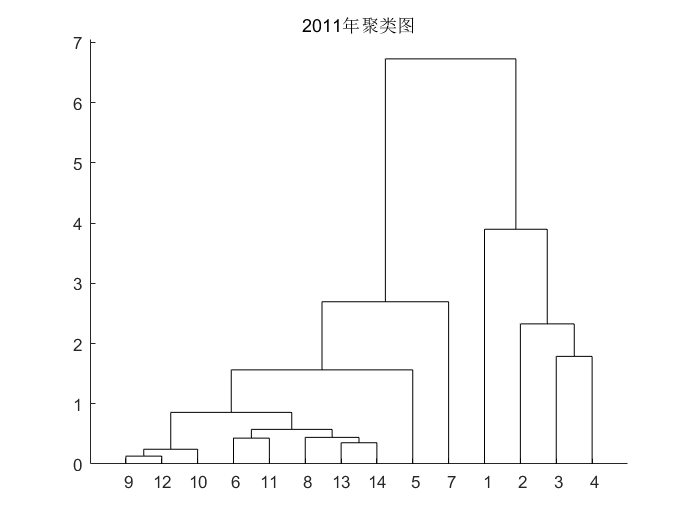

划分成3类的结果如下:
第1类的有:
1中国银行 
第2类的有:
2工商银行 3建设银行 4农业银行 
第3类的有:
5交通银行 6招商银行 7光大银行 8中信银行 9广发银行 10华夏银行 11民生银行 12平安银行 13浦发银行 14兴业银行 
*******************
划分成4类的结果如下:
第1类的有:
7光大银行 
第2类的有:
5交通银行 6招商银行 8中信银行 9广发银行 10华夏银行 11民生银行 12平安银行 13浦发银行 14兴业银行 
第3类的有:
1中国银行 
第4类的有:
2工商银行 3建设银行 4农业银行 
*******************
划分成5类的结果如下:
第1类的有:
2工商银行 
第2类的有:
3建设银行 4农业银行 
第3类的有:
7光大银行 
第4类的有:
5交通银行 6招商银行 8中信银行 9广发银行 10华夏银行 11民生银行 12平安银行 13浦发银行 14兴业银行 
第5类的有:
1中国银行 


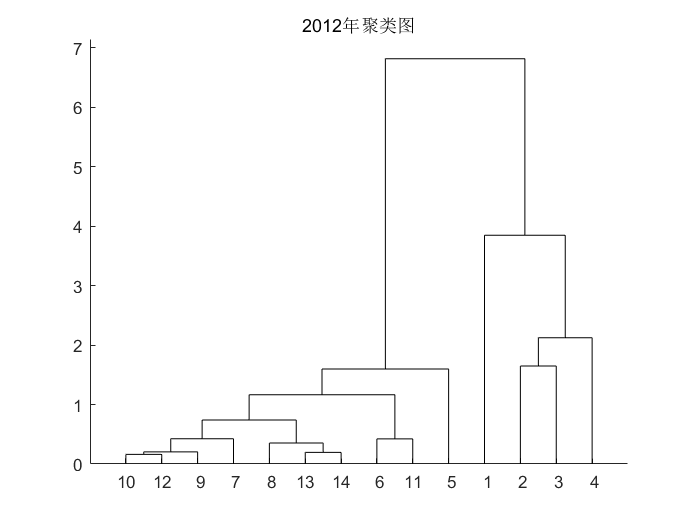

划分成3类的结果如下:
第1类的有:
1中国银行 
第2类的有:
2工商银行 3建设银行 4农业银行 
第3类的有:
5交通银行 6招商银行 7光大银行 8中信银行 9广发银行 10华夏银行 11民生银行 12平安银行 13浦发银行 14兴业银行 
*******************
划分成4类的结果如下:
第1类的有:
4农业银行 
第2类的有:
2工商银行 3建设银行 
第3类的有:
1中国银行 
第4类的有:
5交通银行 6招商银行 7光大银行 8中信银行 9广发银行 10华夏银行 11民生银行 12平安银行 13浦发银行 14兴业银行 
*******************
划分成5类的结果如下:
第1类的有:
2工商银行 
第2类的有:
3建设银行 
第3类的有:
4农业银行 
第4类的有:
1中国银行 
第5类的有:
5交通银行 6招商银行 7光大银行 8中信银行 9广发银行 10华夏银行 11民生银行 12平安银行 13浦发银行 14兴业银行 


%用每年全部数据进行分类
for year=1:3
    yearData=bankData{year,2};
    T=bankData{year,1}+"年聚类图";
    drawCluster(yearData,nameList,T);
end

function drawCluster(Data,nameList,T)
    figure
    gj=zscore(Data);%数据标准化
    y=pdist(gj);%求对象间欧式距离，每行是一个对象
    z=linkage(y,"average");%按类平均法聚类
    h=dendrogram(z);%画聚类图
    set(h,'Color','k')
    title(T);
    for k=3:5
        fprintf("划分成%d类的结果如下:\n",k)
        T=cluster(z,'maxclust',k);%划分k类
        for i=1:k
            tm=find(T==i);%求第i类的对象
            tm=reshape(tm,1,length(tm));
            name={};
            %设置导出内容
            for j=1:length(tm)
                name{j}=[int2str(tm(1,j)) nameList{tm(1,j)}];
            end
            fprintf("第%d类的有:\n",i);
            for l=1:length(name)
                fprintf(name{l}+" ")
            end
            fprintf('\n');
        end
        if k==5
            break
        end
    fprintf("*******************\n");
    end
end